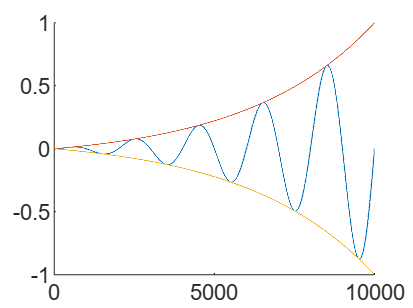

close all
clear
clc
x = linspace(0, 1, 10000);
f = 5;
y = sin(2 * pi * f * x);
% plot(y)
hold on
[A, B] = exponential_envelop(y, 0, 1);
plot(A)
hold on
plot(B)
hold on
plot(-B)

function [output, envelop] = exponential_envelop(y, amp1, amp2)
    [row, col] = size(y); % row = 1, col = n    
    coe = col^(-0.9);
    func = @(x) exp(coe * x);
    [output, envelop] = func_envelop(y, amp1, amp2, func);
end

function [output, envelop] = func_envelop(y, amp1, amp2, func)
    [row, col] = size(y); % row = 1, col = n
    [a, b] = func_fit(1, amp1, col, amp2, func);
    x = 1:1:col;
    envelop = a * func(x) + b;
    output = y .* envelop;
end
function [a, b] = func_fit(x1, y1, x2, y2, func)
    % 计算指数函数参数
    a = (y2 - y1) / (func(x2) - func(x1));
    b = y1 - a * func(x1);
end